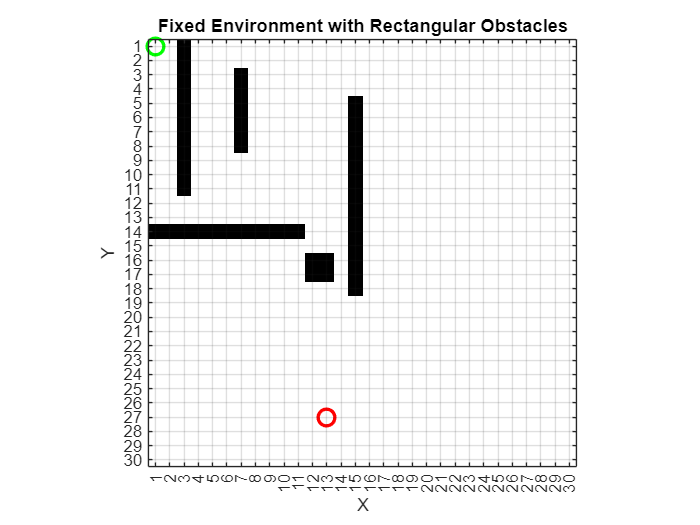

% Function to add rectangular obstacles to the environment
function environment = addRectangle(environment, topLeft, width, height)
    % topLeft: [x, y] coordinates of the top-left corner
    % width: horizontal size of the rectangle
    % height: vertical size of the rectangle
    
    % Define rectangle coordinates
    xStart = topLeft(1);
    yStart = topLeft(2);
    xEnd = min(xStart + width - 1, size(environment, 1)); % Ensure within bounds
    yEnd = min(yStart + height - 1, size(environment, 2)); % Ensure within bounds
    
    % Set obstacle cells to 1
    environment(xStart:xEnd, yStart:yEnd) = 1;
end

% Initialize environment
gridSize = [30, 30];
environment = zeros(gridSize);

% Add obstacles
environment = addRectangle(environment, [3, 1], 1, 11);  % 1x11 rectangle at (3,1)
environment = addRectangle(environment, [1, 14], 11, 1); % 11x1 rectangle at (1,14)
environment = addRectangle(environment, [7, 3], 1,6);    % 1x6 rectangle at (7,3)
environment = addRectangle(environment, [15, 5], 1, 14); % 1x14 rectangle at (15,5)
environment = addRectangle(environment, [12, 16], 2, 2); % 2x2 rectangle at (12,16)

% Define start and goal points
startNode = [1, 1];
goalNode = [13, 27];

% Visualize the environment
figure;
set(gcf, 'Color', [1 1 1]); % White background
imagesc(~environment'); % Invert: obstacles black, free space white
colormap(gray);
hold on;
plot(startNode(1), startNode(2), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Start
plot(goalNode(1), goalNode(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);   % Goal
title('Fixed Environment with Rectangular Obstacles');
xlabel('X'); ylabel('Y');
grid on;

axis equal tight;  % Equal scaling, and fit the plot tightly
set(gca, 'XTick', 1:gridSize(1), 'YTick', 1:gridSize(2)); % Set ticks to match grid cells
set(gca, 'XLim', [0.5, gridSize(1) + 0.5], 'YLim', [0.5, gridSize(2) + 0.5]); % Fit grid boundaries